close all;
clear all;
clc;

fontsize=20;

%including all parent folders up to the file 'code', this makes visible all
%files within this code
addingPathParentFolderByName('COMSOL_2D_turn_chemical_reaction');

Adding matlab path to: D:\code\NN_molecular_communications\Section_IV_BioComputing\COMSOL_2D_turn_chemical_reaction


### Plotting the results of the chemical reaction in 0D 

**Description**: This section plots the exported results for the chemical reaction in COMSOL.

%reading the chemical reaction dataset from COMSOL
% Specify the MAT file for the chemical reaction
csvFileName = 'chemical_reaction_0D.csv';
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview

ans = 8×5 table
       Var1        Var2      Var3        Var4          Var5   
    __________    ______    ______    __________    __________

             0        10        10             0             0
     2.861e-12        10        10    7.7356e-06    7.7356e-06
     5.722e-12        10        10    1.5471e-05    1.5471e-05
    1.1444e-11        10        10    3.0942e-05    3.0942e-05
    2.2888e-11    9.9999    9.9999    6.1885e-05    6.1885e-05
    4.5776e-11    9.9999    9.9999    0.00012377    0.00012377
    9.1553e-11    9.9998    9.9998    0.00024753    0.00024753
    1.8311e-10    9.9995    9.9995    0.00049505    0.00049505


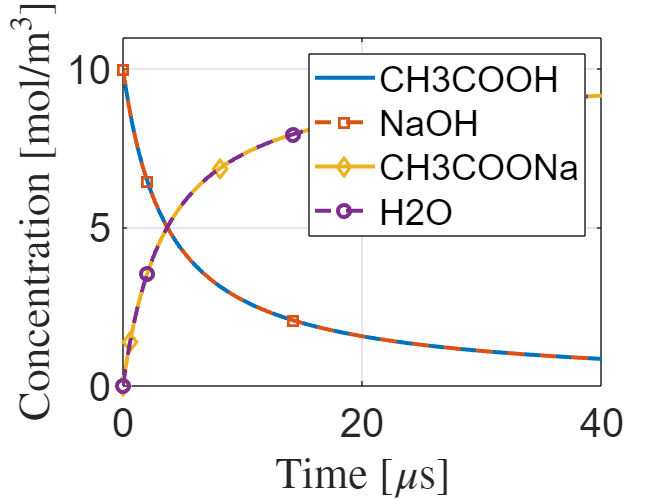

chem_reaction_table=readtable(csvFileName,opts);
%mapping the concentration variables for reactants and products with the
%table columns
time=chem_reaction_table.Var1;
c_CH3COOH=chem_reaction_table.Var2;
c_NaOH=chem_reaction_table.Var3;
c_CH3COONa=chem_reaction_table.Var4;
c_H2O=chem_reaction_table.Var5;


figure;
%Plotting the reactants
plot(time*10^6,c_CH3COOH,'LineWidth',2); grid on; hold on
plot(time*10^6,c_NaOH,'s--','MarkerIndices',15:30:length(c_NaOH),'LineWidth',2);
%Plotting the products
plot(time*10^6,c_CH3COONa,'d-','MarkerIndices',5:30:length(c_CH3COONa),'LineWidth',2); grid on; hold on
plot(time*10^6,c_H2O,'o--','MarkerIndices',15:30:length(c_NaOH),'LineWidth',2);

xlabel('Time [$\mu$s]','Interpreter','latex');
ylabel ('Concentration [mol/m$^3$]','Interpreter','latex');
legend('CH3COOH','NaOH','CH3COONa','H2O');
set(gca,'FontSize',fontsize);
% axis([0 time(end/2)*10^6 0 1.1*max(c_CH3COOH)]);
axis([0 40 0 1.1*max(c_CH3COOH)]);

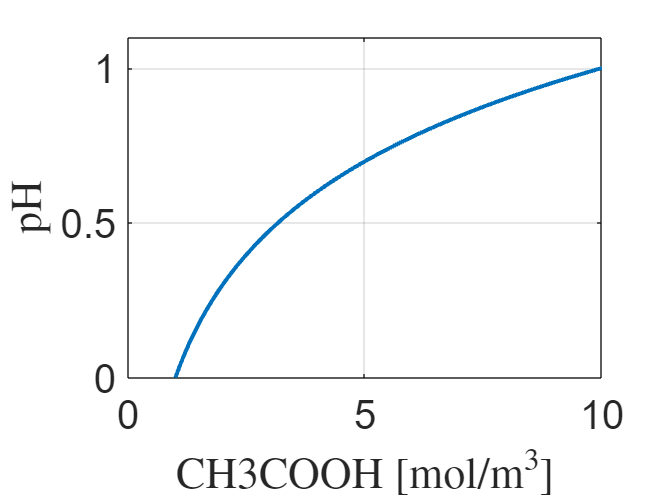

figure;
pH=log10(c_CH3COOH);
plot(c_CH3COOH,pH,'LineWidth',2); grid on; hold on
ylabel ('pH','Interpreter','latex');
xlabel('CH3COOH [mol/m$^3$]','Interpreter','latex');

% legend('CH3COOH','pH');
set(gca,'FontSize',fontsize);
axis([0 time(end/2)*10^6 0 1.1*max(c_CH3COOH)]);
axis([0 max(c_CH3COOH) 0 1.1*max(pH)]);

### Plotting the velocity within the pipe

**Description:** This block plots the velocity fluid within the pipe. The fluid velocity is exported first from COMSOL and imported in Matlab. The file is accesible in the dataset local folder.

%reading the velocity surface in COMSOL
% Specify the MAT file for the chemical reaction
csvFileName = 'velocity.csv';
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview

ans = 8×3 table
       Var1          Var2          Var3  
    __________    ___________    ________

         3e-05      1.397e-06    0.046938
     2.899e-05     1.0035e-06    0.032677
         3e-05    -4.2352e-22           0
     2.846e-05              0           0
    2.8862e-05     2.1833e-06    0.060404
         3e-05     2.8308e-06    0.073645
     2.764e-05     1.2495e-06    0.038029
    2.6879e-05              0           0


velocity_table=readmatrix(csvFileName,opts);
%mapping the concentration variables for reactants and products with the
%table columns

x = velocity_table(:,1);    % x-coordinate  
y = velocity_table(:,2);    % y-coordinate  
V = velocity_table(:,3);    % velocity magnitude  

% Determine grid size (assumes x repeats every Ny points)
x_unique = unique(x);
y_unique = unique(y);

[Xq,Yq] = meshgrid( x_unique, y_unique );  % Ny×Nx grid of query points
Zq = griddata(x, y, V, Xq, Yq, 'linear');  % interpolate V onto that grid

%deleting the remainder of interporlation
Zq(isnan(Zq)) = 0;
%we use rectangles to delete the remainders of interpolation
x_rect=190

x_rect = 190

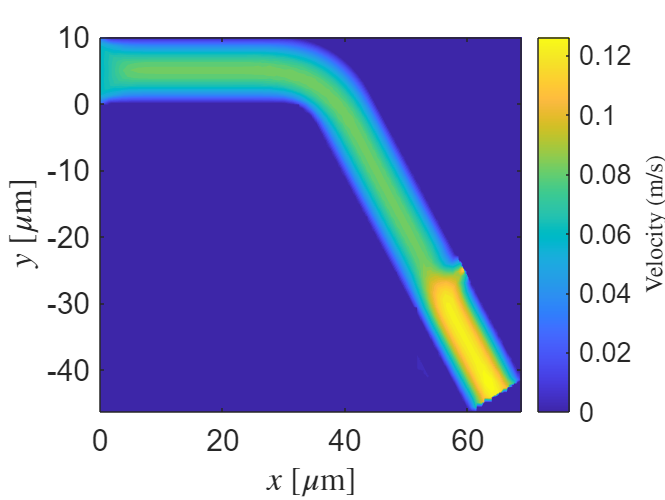

y_rect=320;
Zq(1:y_rect,1:x_rect)=zeros(y_rect,x_rect);
%Rectangle 2
x_init_rect=x_rect;
x_rect=305;
y_init_rect=1;
y_rect=200;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);
%Rectangle 3
x_init_rect=x_rect;
x_rect=360;
y_init_rect=1;
y_rect=140;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);
%Rectangle 4
x_init_rect=x_rect;
x_rect=400;
y_init_rect=1;
y_rect=100;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);

figure;
contourf(Xq*10^6,Yq*10^6,Zq,40, 'LineColor','none');
% contourf(Xq,Yq,Zq,40, 'LineColor','none');
shading interp;
% add and label the colorbar
cb = colorbar;                        % add colorbar
cb.Label.String    = 'Velocity (m/s)';% set its label
cb.Label.FontSize  = 12;              % tweak font size
cb.Label.Interpreter = 'latex';       % if you want LaTeX formatting
xlabel('$x$ [$\mu$m]','Interpreter','latex');
ylabel('$y$ [$\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Plotting the concentration level within the pipe

**Description:** This block plots the concentration of CH3COO and NaOH concentration within the pipe. The fluid velocity is exported first from COMSOL and imported in Matlab. The file is accesible in the dataset local folder.

ans = 8×3 table
       Var1          Var2         Var3  
    __________    ___________    _______

    2.9506e-05     4.6835e-07      0.311
    2.9268e-05              0    0.30245
         3e-05    -4.2352e-22    0.30279
         3e-05     7.1429e-07     0.3084
    2.8897e-05     5.3458e-07     0.3167
    2.8537e-05              0    0.30871
         3e-05     1.4286e-06    0.24465
     2.936e-05     1.0938e-06    0.29974


x_rect = 190

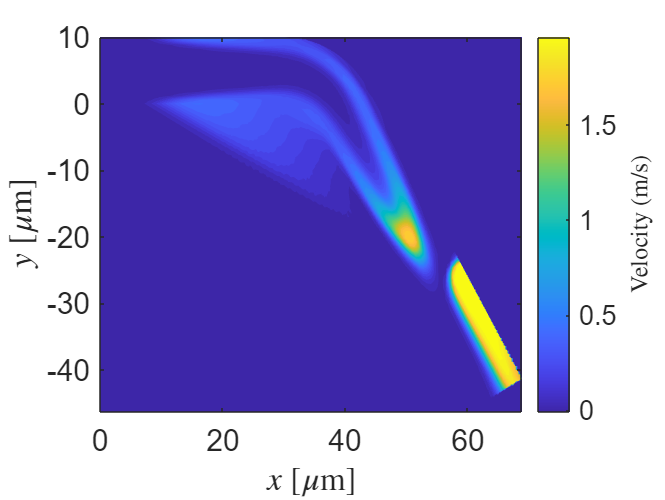

%reading the velocity surface in COMSOL
% Specify the MAT file for the chemical reaction
csvFileName = 'CH3COOH_NaOH.csv';
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview
conc_table=readmatrix(csvFileName,opts);
%mapping the concentration variables for reactants and products with the
%table columns

x = conc_table(:,1);    % x-coordinate  
y = conc_table(:,2);    % y-coordinate  
V = conc_table(:,3);    % velocity magnitude  

% Determine grid size (assumes x repeats every Ny points)
x_unique = unique(x);
y_unique = unique(y);

[Xq,Yq] = meshgrid( x_unique, y_unique );  % Ny×Nx grid of query points
Zq = griddata(x, y, V, Xq, Yq, 'linear');  % interpolate V onto that grid

%deleting the remainder of interporlation
Zq(isnan(Zq)) = 0;
%we use rectangles to delete the remainders of interpolation
x_rect=190
y_rect=320;
Zq(1:y_rect,1:x_rect)=zeros(y_rect,x_rect);
%Rectangle 2
x_init_rect=x_rect;
x_rect=305;
y_init_rect=1;
y_rect=200;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);
%Rectangle 3
x_init_rect=x_rect;
x_rect=360;
y_init_rect=1;
y_rect=140;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);
%Rectangle 4
x_init_rect=x_rect;
x_rect=400;
y_init_rect=1;
y_rect=100;
Zq(y_init_rect:y_rect,x_init_rect:x_rect)=zeros(y_rect-y_init_rect+1,x_rect-x_init_rect+1);

figure;
contourf(Xq*10^6,Yq*10^6,Zq,40, 'LineColor','none');
% contourf(Xq,Yq,Zq,40, 'LineColor','none');
shading interp;
% add and label the colorbar
cb = colorbar;                        % add colorbar
cb.Label.String    = 'Velocity (m/s)';% set its label
cb.Label.FontSize  = 12;              % tweak font size
cb.Label.Interpreter = 'latex';       % if you want LaTeX formatting
xlabel('$x$ [$\mu$m]','Interpreter','latex');
ylabel('$y$ [$\mu$m]','Interpreter','latex');
set(gca,'FontSize',fontsize);

### Loading the COMSOL parameters

Description: This block loads the parameters used in COMSOL for the simulation. The parameters here exported comes from two files:

- `parameters_2D.csv`: This file contains the parameters in the 'Model Builder/Global Definitions/Parameters 1' in COMSOL. This file was generated in COMSOL using the saving button in the Settings window after selecting the `Parameters 1 `in the Model Builder window.

- `density_H2O.csv`: This file comprises the definition used by COMSOL to evaluate the density of water with the temperature. The file was created in COMSOL with the saving function accesible in the setting windows. The density is evaluated for the water, which is found in the Model Builder window under 'Component 1/Materials/H2O/Basic/rho_liquid_2'.

- `viscosity_H2O.csv`: This file comprises the definition used by COMSOL to evaluate the viscosity of water with the temperature. The viscosity is evaluated for the water, which is found in the Model Builder window under 'Component 1/Materials/H2O/Basic/eta_liquid_1'. The file was created in COMSOL with the saving function accesible in the setting windows. 

fontsize=15;
% Specify the MAT file for the parameters
csvFileName = 'parameters_2D.csv';
%entry from the table

ans = 8×3 table
                  Var1                                Var2                                                                       Var3                                                      
    _________________________________    ______________________________    ________________________________________________________________________________________________________________

    {'width_cylinder_in_1'          }    {'90[um]'                    }    {'Length of the cilinder input 1'                                                                              }
    {'radius_cylinder_1'            }    {'5[um]'                     }    {'Radius of the cilinder 1'                                                                                    }
    {'width_cylinder_out_1'         }    {'30[um]'                    }    {'Length of the cilinder output 1'                    

opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview
table_parameters=readtable(csvFileName,opts);

% Specify the MAT file for the density
csvFileName = 'density_H2O.csv';
%entry from the table

ans = 2×3 table
     Var1      Var2                             Var3                         
    ______    ______    _____________________________________________________

    273.15       283    {'972.7578145+0.2084*T^1-4.0E-4*T^2'                }
       283    373.16    {'345.28+5.749816*T^1-0.0157244*T^2+1.264375E-5*T^3'}


opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview
table_density=readtable(csvFileName,opts);

% Specify the MAT file for the density
csvFileName = 'viscosity_H2O.csv';
%entry from the table

ans = 1×3 table
    Var1     Var2                                                       Var3                                                   
    ____    ______    _________________________________________________________________________________________________________

    265     423.16    {'exp(1.47297892E+11/T^4 - 1.56916127E+09/T^3 + 6.52798499E+06/T^2 - 1.10421451E+04/T - 2.86320560E+00)'}


opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
preview(csvFileName,opts) %data file preview
table_viscosity=readtable(csvFileName,opts);


### Reading the parameters from COMSOL

**Description**: The name of the Matlab variables follows the names within the parameters table. The name o fthe variables are given within the first column of the table, while their values in the second column. This code calls the function getVarTable whenever the value is numeric, or to the function getExpTable whenever the value is evaluated within an expresssion.

%define the variables of interest
%geometric parameters
radius_cylinder_1=0;
width_cylinder_in_1=0;
width_cylinder_out_1=0;
angle_turn_1_rad=0;
r_in_1=0;
r_out_1=0;
L=0;%total widht of the rectangle pipe
%flow parameters
p0=0;%this is derived from COMSOL parameters if the Inlet  specify the pressure level within the Laminar Flow(spf), otherwise it must be recalculated.
v0=0;%this is derived from COMSOL parameters if the Inlet  specify the velocity level within the Laminar Flow(spf), otherwise it must be recalculated.
%Sodium parameters
c_Na=0;%concentration of released particles
c_CH3COOH_ini=0;%concentration of released particles
D_Na=0;%diffusion coefficient of released particles
d_Na=0;%diameter of the released particles
M_Na=0;%molar mass of the released particles
rho_Na=0;%density of released particles
time_delta=0;%sampling time
time_simul=0;%total simulation time
T=293.15;%default model input in Kelvin



width_cylinder_in_1 = 9.0000e-05

[var,factor]=getVarTable(width_cylinder_in_1,table_parameters);
width_cylinder_in_1=eval(var{1})*factor

width_cylinder_out_1 = 3.0000e-05

[var,factor]=getVarTable(width_cylinder_out_1,table_parameters);
width_cylinder_out_1=eval(var{1})*factor

radius_cylinder_1 = 5.0000e-06

[var,factor]=getVarTable(radius_cylinder_1,table_parameters);
radius_cylinder_1=eval(var{1})*factor

angle_turn_1_rad = 1.0472

[var,factor]=getVarTable(angle_turn_1_rad,table_parameters);
angle_turn_1_rad=eval(var{1})*factor

r_in_1 = 6.0000e-06

[var,factor]=getVarTable(r_in_1,table_parameters);
r_in_1=eval(var{1})*factor

r_out_1 = 1.6000e-05

[var,factor]=getVarTable(r_out_1,table_parameters);
r_out_1=eval(var{1})*factor

L = 1.3152e-04

[var,factor]=getVarTable(L,table_parameters);
L=eval(var{1})*factor

p0 = 4.6663e+03

[var,factor]=getVarTable(p0,table_parameters);
p0=eval(var{1})*factor

v0 = 0.0605

[var,factor]=getVarTable(v0,table_parameters);
v0=eval(var{1})*factor

c_Na = 10

[var,factor]=getVarTable(c_Na,table_parameters);
c_Na=eval(var{1})*factor

c_CH3COOH_ini = 10

[var,factor]=getVarTable(c_CH3COOH_ini,table_parameters);
c_CH3COOH_ini=eval(var{1})*factor

D_Na = 1.3300e-09

[var,factor]=getVarTable(D_Na,table_parameters);
D_Na=eval(var{1})*factor
[var,factor]=getVarTable(D_CH3COOH,table_parameters);
D_CH3COOH=eval(var{1})*factor

M_Na = 0.0230

[var,factor]=getVarTable(M_Na,table_parameters);
M_Na=eval(var{1})*factor

rho_Na = 0.2299

[var,factor]=getVarTable(rho_Na,table_parameters);
rho_Na=eval(var{1})*factor

time_delta = 2.5000e-05

[var,factor]=getVarTable(time_delta,table_parameters);
time_delta=eval(var{1})*factor

time_simul = 0.0100

[var,factor]=getVarTable(time_simul,table_parameters);
time_simul=eval(var{1})*factor

%Evaluating the viscosity as follows from the COMSOL definition
str=table_viscosity{1,3};
mu_Water=eval(str{1});

%Evaluating the viscosity as follows from the COMSOL definition
str=table_viscosity{1,3};
mu_Water=eval(str{1});

%Evaluating the density as follows from the COMSOL definition
%looking for the temperature range
T1=table_density{1,1};
T2=table_density{1,2};
T3=table_density{2,1};
T4=table_density{2,2};

if(T>=T1 && T<=T2)
    str=table_density{1,3};
    rho_Water=eval(str{1});
elseif(T>=T3 && T<=T4)
    str=table_density{2,3};
    rho_Water=eval(str{1});
else
    error('The temperature of your system is not in the range of COMSOL')
end


### Evaluating the characteristic flow velocity

**Description**: This section evaluates the profile velocity from theoretical formulations, according to the Poiseuile flow and contrast results with the derived in COMSOL. When the Inlet pressure is given as a condition the resulting profile develops as [2, Eq. 4.9 pag. 54]


$$v(r)=\frac{\Delta p}{2\mu L}(a^2-r^2)$$


where $\Delta p$ is the inlet pressure, $\mu$ is the viscosity of the medium (water), $L$ is the length(width) of the pipe, $a$ is the radius of the pipe, and $r$ is the radial-axis coordinates. The case $r=0$ denotes the center in the cross-sectional area of the pipe.

When the inlet speed is given, this value specifies the maximum velocity, i.e., $\bar{v}=\int_0^{a}{v(r)dr}=\frac{2}{3}v_\mathrm{m}$, where $v_\mathrm{m}$ is the maximum velocity (at the center of the pipe). In such a case, the resulting $\Delta p=\frac{3\mu L\bar{v}}{a^2}$, and the velocity profile is


$$v(r)=\frac{3\bar{v}}{2a^2}(a^2-r^2)$$


%COMSOL simulation
%reading the velocity profile in COMSOL
% Specify the MAT file for the velocity
csvFileName = 'velocity_vs_r.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_velocity=readtable(csvFileName,opts);
v_r_COMSOL=table_velocity.Var3;
%Evaluating the average speed from COMSOL

v_mean_COMSOL = 0.0553

v_mean_COMSOL=mean(v_r_COMSOL)

v_max_COMSOL = 0.0843

v_max_COMSOL=max(v_r_COMSOL)

%Theoretical evaluation
syms r v
L=width_cylinder_in_1+angle_turn_1_rad*(r_in_1+r_out_1)/2+width_cylinder_out_1;
%Given the Inlet velocity in COMSOL we evaluating the average pressure as
p0=3*mu_Water*L*v_mean_COMSOL/radius_cylinder_1^2;
%p0=8*mu_Water*L*v0/radius_cylinder_1^2;
%For the velocity profile we follow [1, Eq. (2.33a) pp.28] except for a
%factor of 2. This factor is correctly stated in [2, Eq. 4.9 pag. 54]
v(r)=p0/(2*mu_Water*L)*(radius_cylinder_1^2-r^2);
% v(r)=3/2*v0/radius_cylinder_1^2*(radius_cylinder_1^2-r^2);

%Validating the calculations
r_vector=linspace(-radius_cylinder_1,radius_cylinder_1,100);
%Evaluating the characteristic velocity

v0_char = 0.0553

v0_char=double(int(v(r),r,0,radius_cylinder_1)/radius_cylinder_1)
%Evaluating the maximum velocity

v_center = 0.0830

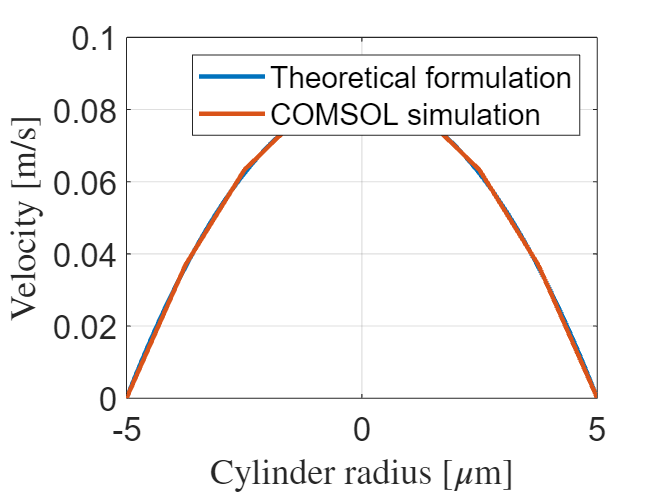

v_center=double(v(0))

figure;
plot(r_vector*10^6,double(subs(v,r,r_vector)),'LineWidth',2); grid on; hold on
%the jumps in the COMSOL plot is due to a poor resolution of the mesh
plot((table_velocity.Var2-max(table_velocity.Var2)/2)*10^6,table_velocity.Var3,'LineWidth',2);
xlabel('Cylinder radius [$\mu$m]','Interpreter','latex');
ylabel ('Velocity [m/s]','Interpreter','latex');
legend('Theoretical formulation','COMSOL simulation')

set(gca,'FontSize',fontsize);

### Evaluating the Reynold number

**Description**: The Reynold ($\mathrm{Re}$) number defines the ratio inertial/viscous forces. In a microfluidic environment where the fluid is expected to be laminar the viscous forces should dominate. Thereby we expect $\mathrm{Re}<1$.

%This evaluation follows [1, Eq. (3.36) pp. 52]

Re = 0.5535

Re=rho_Water/mu_Water*v0_char*2*radius_cylinder_1

### Evaluating the Péclet number

**Description**: The Péclet ($Pe$) number defines the ratio (diffusion time)/(convection time). This ratio defines wheter diffusion or convection dominates. If the convection time is less than diffussion, then the particles haven't diffused within the convection time interval, in this case $Pe<1$. Whenever the convection time is larger than diffusion, it means that the particles has diffused before the convection time, i.e., $Pe>1$. The Péclet number is analyzed taking the diffusion time as the one needed for the particles to travel along the radius of the microfluid, i.e., given by $\tau_\mathrm{diff}^r=\frac{r^2}{D}$, where $r$ is the radius of the microfluidic pipe and $D$ is the diffusion coefficient of the particle. Similarly, is for the convection time, given by $\tau_\mathrm{conv}^r=\frac{r}{V_0}$, where $V_0$ is the average fluid velocity within the Pouseille flow.

%This evaluation follows [1,Eq. (4.44) pp.75]

Pe = 208.0502

Pe=radius_cylinder_1*v0_char/D_Na


The particles are observed (at any point in x-axis) to diffuse homogenously whenever the condition $Pe\ll \frac{4L}{r}$ is met, where $L$ is the length of the microfluidic channel; see [1, Eq. (4.52) pp. 77]. Besides, diffusion effectively ocurred at any observation point $x$ whenever the dispersion coefficient satisfies $D_\mathrm{eff}\gg D$, where $D_\mathrm{eff}=\frac{r^2V_0^2}{48D}$ or $Pe\ll \sqrt{48}$; see [1, Eq.(4.54) pp.77].  Both conditions entails the relation:

$\sqrt{48}\ll Pe \ll 4\frac{L}{r}$.       (1)

if(Pe<4*L/radius_cylinder_1)
    disp(['Concentration is constant along the x-axis'])
else
    disp(['Concentration is not constant along the x-axis'])
end


Concentration is not constant along the x-axis


if(Pe>sqrt(48))
    disp(['Diffusion occurred along the radial axis'])
else
    disp(['Diffusion hasn''t occurred along the axis'])
end

Diffusion occurred along the radial axis


### Evaluating the Effective Diffusion

D_eff=radius_cylinder_1^2*v0^2/48/D_CH3COOH


D_eff = 1.4355e-06

### Evaluating the concentration level

**Description**: This section evaluates the concentration level observed at the ouptup of the rectangular pipes (straigth and turning). The evaluation is performed theoretical and following the simulations provided by COMSOL. Following COMSOL we have the following files

- `concentration_outlet_turn_rectangle.csv`: This file stores the average concentration for the inclined outlet line. This line develops a similar condition to the outlet of the turning channel.

- `concentration_outlet_turn.csv`: This file stores the average concentration for the outlet of the turning channel.

Regarding the theoretical calculation we follow the Taylor's model, see [1, Sec. 4.5]. Whenever the Péclet number fulfill the condition in the above Eq. (1), the particles difussion is homogeneous along the $x$-axis and can be evaluated with the non-convection condition, i.e., free difussion in moved coordinate system. For the free difussion scenario, we regard to the case where there the diffusing substance concentrated initially on the negative side of $x'$ as [3, Sec. 2.2.3 pp. 13]

$C=C_0$, $x'<0$, $C=0$, $x'>0$, $t=0$.

where the solution is [3, Eq. (2.14)]

$C(x',t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x'}{2\sqrt{Dt}}$.             (2)

Then, within the moved coordinate system $x'=x-v_0t$ and $D=D_\mathrm{eff}$, yielding

$C(x,t)=\frac{1}{2}C_0\, \mathrm{erfc}\frac{x-v_0t}{2\sqrt{D_\mathrm{eff}\,t}}$,          (3)

where [1, Eq. (4.54) pp. 77]

$D_\mathrm{eff}=\frac{a^2v_0^2}{48D}$,                                   (4)

is the effective diffusion coefficient, and $v_0$ is the characteristic speed, here given as the average speed within the microfluidic pipe.

Besides, as the turning channel introduces the reacetrack effect, a turn is also similar to additionally shift the coordinate $x$ in Eq. (3) on a straight pipe. As the concentration solution en Eq. (3) is valid regardless $y$, after the turn each lamina well be delayed in the amount $l-l_\mathrm{in}=\phi r_l - \phi r_\mathrm{in}=\phi \Delta r_l$, where $l$ refers to the length of the arcus on a given lamina, $\phi$ is the angle of the turn and $r_l$ is the radius of the arc. As such, Eq.(3) after a turn becomes


$$C(x,t)=\int_{r_\Delta=0}^{r_\Delta=r_\mathrm{out}-r_\mathrm{in}}\frac{1}{2}C_0\, \mathrm{erfc}\left(\frac{x-v_0t-\phi r_\Delta}{2\sqrt{D_\mathrm{eff}\,t}}\right)dr_\Delta$$


which is evaluated after using the primitive of this integral as


$$\int{\mathrm{erfc}(x)dx}=x\cdot\mathrm{erfc}(x)-\frac{e^{-x^2}}{\sqrt{\pi}}$$


yields


$$C(x,t)=2\,\mathrm{dr}+\mathrm{dr}\,\left(\mathrm{erf}\left(\frac{\mathrm{angle}\,\mathrm{dr}-x+t\,v_{0}}{2\,\sqrt{D\,t}}\right)-1\right)-\frac{\left(x-t\,v_{0}\right)\,\left(\mathrm{erf}\left(\frac{\mathrm{angle}\,\mathrm{dr}-x+t\,v_{0}}{2\,\sqrt{D\,t}}\right)-1\right)}{\mathrm{angle}}-\frac{\left(x-t\,v_{0}\right)\,\left(\mathrm{erf}\left(\frac{x-t\,v_{0}}{2\,\sqrt{D\,t}}\right)+1\right)}{\mathrm{angle}}-\frac{2\,{\mathrm{e}}^{-\frac{{\left(x-t\,v_{0}\right)}^2}{4\,D\,t}}\,\sqrt{D\,t}}{\mathrm{angle}\,\sqrt{\pi }}+\frac{2\,{\mathrm{e}}^{-\frac{{\left(\mathrm{angle}\,\mathrm{dr}-x+t\,v_{0}\right)}^2}{4\,D\,t}}\,\sqrt{D\,t}}{\mathrm{angle}\,\sqrt{\pi }}$$


%Reading the concentration from COMSOL
% Specify the MAT file for the concentration at the outlet
csvFileName = 'CH3COOH_Outlet_Pipe_Out.csv';
%entry from the table
opts=detectImportOptions(csvFileName,'ReadVariableNames', false);
% preview(csvFileName,opts) %data file preview
table_conc_outlet_turn=readtable(csvFileName,opts);

%Matlab code to evaluate the integral
syms z x Delta_r rd t

% Define the substitution for x
z = (x - v0_char*t - angle_turn_1_rad*rd) / (2*sqrt(D_eff*t));

% Define the integrand
integrand = erfc(z);

% Perform the symbolic integration from r = 0 to r = dr
I = simplify(int(integrand, rd, 0, Delta_r))/(Delta_r);
I_vs_t=subs(I,[Delta_r,x],[(r_out_1-r_in_1),width_cylinder_in_1+angle_turn_1_rad*r_in_1+width_cylinder_out_1]);

% % Display the result
% disp('The integral of erfc(x) from r = 0 to r = dr is:')
% disp(latex(I))

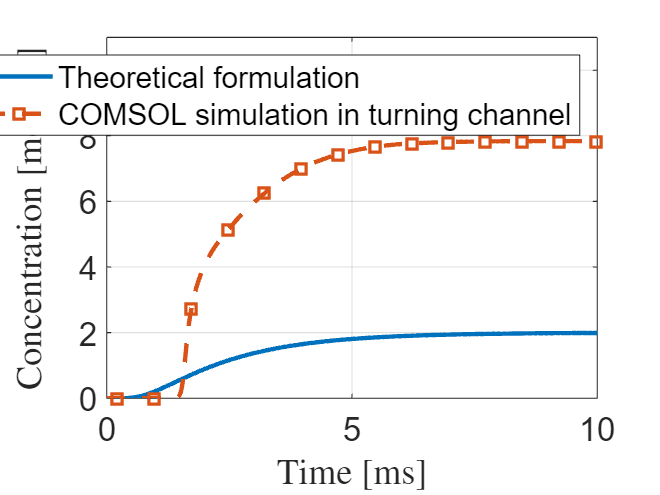


c=c_CH3COOH_ini*1./2.*erfc((L-v0_char*t)./(2*sqrt(D_eff*t)));
c=I;
figure;
time=table_conc_outlet_turn.Var1;
plot(time(7:end)*10^3,subs(I_vs_t,t,time(7:end)'),'LineWidth',2); grid on; hold on;
plot(table_conc_outlet_turn.Var1*10^3,table_conc_outlet_turn.Var2,'s--','MarkerIndices',15:30:length(table_conc_outlet_turn.Var2),'LineWidth',2);
xlabel('Time [ms]','Interpreter','latex');
ylabel ('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);
legend('Theoretical formulation','COMSOL simulation in turning channel');
axis([0 time_simul*10^3 0 c_Na*1.1])

L/v0_char*10^3

ans = 2.3765

L^2/D_Na

ans = 13.0055

syms t
c=1./sqrt(4*pi*D_Na*t)^3.*exp(-(L-v0_char*t).^(2)./(4*D_Na*t));
figure;
fplot(c,[0.01 0.0109],'LineWidth',2); grid on;
xlabel('Time [s]','Interpreter','latex');
ylabel ('Concentration [mol/m$^3$]','Interpreter','latex');
set(gca,'FontSize',fontsize);

function addingPathParentFolderByName(targetName)
    % Start from the current directory
    currFolder = pwd;
    found = false;
    
    % Continue searching until you reach the root folder
    while true
        % Get the parent folder
        [parentFolder, currentName] = fileparts(currFolder);
        
        % Check if the current folder's name is the target
        if strcmpi(currentName, targetName)
            found = true;
            break;
        end
        
        % If we've reached the root or no change, exit the loop
        if isempty(parentFolder) || strcmp(currFolder, parentFolder)
            break;
        end
        
        % Move one level up
        currFolder = parentFolder;
    end

    if found
        addpath(genpath(currFolder));
        fprintf('Adding matlab path to: %s\n', currFolder);
    else
        error('Folder named "%s" not found in any parent directory.', targetName);
    end
end

function [value,factor]= getVarTable(var,table)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);

%find the corresponding entry within the table of parameters
for i=1:numel(table(:,1))
    entry_str=strcmp(table{i,1},varName);
    if entry_str
        entry_table=i;
        break
    end
end

%validating
if isempty(entry_table)
    error('Table has no column named "%s".', varName);
    value=NaN;
    factor=NaN;
else
    str=table{entry_table,2};
    if(isempty(findstr(str{1},'[')))
        value=table{entry_table,2};
    else
        value=extractBefore(table{entry_table,2},'[');
    end
    %var=eval(str{1});
    unit = extractBetween(table{entry_table,2}, "[", "]"); % e.g. ["um"; "mm"; "nm"; "m"]
    if isempty(unit)
        factor=1;
    else
        %Define your conversion map to meters
        convMap = containers.Map( ...
            {'nm','um','mm','cm','m','km','rad','s','ms','us','ns','Pa','mmHg','m/s','mol/m^3','m^2/s','g/mol'}, ...
            [1e-9,1e-6,1e-3,1e-2,1,1e3,1,1,1e-3,1e-6,1e-9,1,133.322,1,1,1,1e-3] );
        %Finding the conversion factors
        if isKey(convMap, unit)
            factor = convMap(unit{1});
        else
            error('Unit "%s" not recognized.', unit{1});
        end
    end
    
end
end

function varName = getVarName(var)
%This function extract the value of the variable specified in var within
%the table specified in table

% getVarName   Extract the name of the workspace variable
varName = inputname(1);
end


## References

[1] H. Bruus, *Theoretical Microfluidics*. 2008. doi: [10.1093/oso/9780199235087.001.0001](https://doi.org/10.1093/oso/9780199235087.001.0001).  

[2] Howard C. Berg. 1993. Random Walks in Biology. Princeton University Press.

[3] J. Crank. 1986. The Mathematics of Diffusion. Oxford University Press.